syms mu_0 I n l z r theta_1 theta_2
syms p l_mag

assume([mu_0 I n l z r p l_mag theta_1 theta_2], 'real')
assumeAlso([z r], 'positive')

struct_params = struct();
struct_params.mu_0 = 6.3e-3; % m kg /(s^2 A^2)
struct_params.n = 50; % # of turns
struct_params.r = 0.01; % Radius (m)
struct_params.p = 48; % Pole strength (amp-meters)
struct_params.l_mag = 0.05; % Length of magnet (m)
struct_params.l = 0.02; % Length of inductor (m)

B = (mu_0/2)*I*(n/l) * int(r^2/((r^2+z^2)^1.5), z, z, z+l)

$$B = -\frac{\text{I}\,\mu_{0}\,n\,\left(\frac{z}{\sqrt{r^{2}+z^{2}}}-\frac{l+z}{\sqrt{{\left(l+z\right)}^{2}+r^{2}}}\right)}{2\,l}$$

#### Calculate force:

Using $F = \nabla(\vec m \cdot \vec B)$, but with $\vec m = p\cdot l_{mag} \hat{k}$ where $p$ is the pole strength of the magnet and $l \hat{k}$ is the vector pointing from south to north pole of the magnet

force = p*l_mag*simplify(diff(B, z))

$$force = \begin{array}{l} \frac{\text{I}\,l_{\mathrm{mag}}\,\mu_{0}\,n\,p\,\left(\frac{1}{\sqrt{\sigma_{1}}}-\frac{1}{\sqrt{r^{2}+z^{2}}}+\frac{z^{2}}{{\left(r^{2}+z^{2}\right)}^{3/2}}-\frac{\left(2\,l+2\,z\right)\,\left(l+z\right)}{2\,{\sigma_{1}}^{3/2}}\right)}{2\,l}\\ \mathrm{where}\\ \sigma_{1}={\left(l+z\right)}^{2}+r^{2} \end{array}$$

#### Linerization:

syms a % Linearization point
assume(a, 'real')
% linearized = f'(a) * (z - a) + f(a) - point-slope form
lin_force = subs(diff(force, z), z, a) * (z - a) + subs(force, z, a)

$$lin\_force = \begin{array}{l} \frac{\text{I}\,l_{\mathrm{mag}}\,\mu_{0}\,n\,p\,\left(\frac{1}{\sqrt{\sigma_{1}}}-\frac{1}{\sqrt{\sigma_{3}}}+\frac{a^{2}}{{\sigma_{3}}^{3/2}}-\frac{\left(a+l\right)\,\sigma_{2}}{2\,{\sigma_{1}}^{3/2}}\right)}{2\,l}+\frac{\text{I}\,l_{\mathrm{mag}}\,\mu_{0}\,n\,p\,\left(a-z\right)\,\left(\frac{\sigma_{2}}{{\sigma_{1}}^{3/2}}-\frac{3\,a}{{\sigma_{3}}^{3/2}}+\frac{3\,a^{3}}{{\sigma_{3}}^{5/2}}+\frac{a+l}{{\sigma_{1}}^{3/2}}-\frac{3\,\left(a+l\right)\,{\sigma_{2}}^{2}}{4\,{\sigma_{1}}^{5/2}}\right)}{2\,l}\\ \mathrm{where}\\ \sigma_{1}={\left(a+l\right)}^{2}+r^{2}\\ \sigma_{2}=2\,a+2\,l\\ \sigma_{3}=a^{2}+r^{2} \end{array}$$

force_particular = subs(force, struct_params);
B_particular = subs(B, struct_params);
lin_force_particular = subs(lin_force, struct_params);

f_force = matlabFunction(force_particular);
f_B = matlabFunction(B_particular);
f_lin_force_particular = matlabFunction(lin_force_particular);

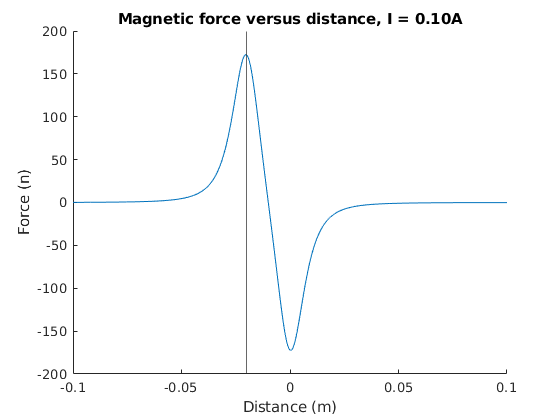

% Constant current, varying position:
I_val = 0.1; % amps
z_val = linspace(-0.1, 0.1, 1000); % meters
v_force = f_force(I_val, z_val);

figure()
hold on

plot(z_val, v_force);
xline(-struct_params.l);

title(sprintf("Magnetic force versus distance, I = %.2fA", I_val))
xlabel("Distance (m)")
ylabel("Force (n)")

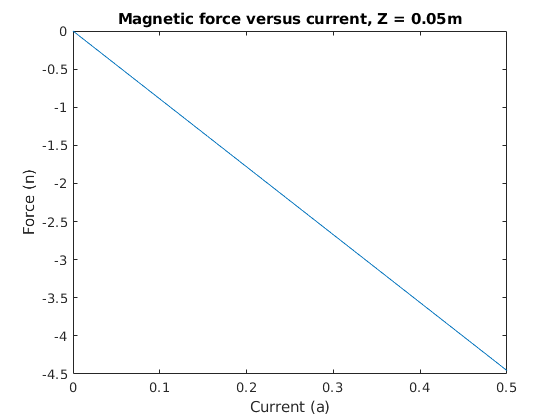

z_val = 0.05; % meters
I_val = linspace(0, 0.5, 1000); % amps
v_force = f_force(I_val, z_val);

figure()
plot(I_val, v_force)
title(sprintf("Magnetic force versus current, Z = %.2fm", z_val))
xlabel("Current (a)")
ylabel("Force (n)")